clear all
close all
t=0:0.01:1;
y=sawtooth(2*pi*4*t);
minimo=min(y);
y=y-minimo

y =          0    0.0800    0.1600    0.2400    0.3200    0.4000    0.4800    0.5600    0.6400    0.7200    0.8000    0.8800    0.9600    1.0400    1.1200    1.2000    1.2800    1.3600    1.4400    1.5200    1.6000    1.6800    1.7600    1.8400    1.9200         0    0.0800    0.1600    0.2400    0.3200    0.4000    0.4800    0.5600    0.6400    0.7200    0.8000    0.8800    0.9600    1.0400    1.1200    1.2000    1.2800    1.3600    1.4400    1.5200    1.6000    1.6800    1.7600    1.8400    1.9200


maximo=max(y)

maximo = 1.9200

y=255/maximo*y

y =          0   10.6250   21.2500   31.8750   42.5000   53.1250   63.7500   74.3750   85.0000   95.6250  106.2500  116.8750  127.5000  138.1250  148.7500  159.3750  170.0000  180.6250  191.2500  201.8750  212.5000  223.1250  233.7500  244.3750  255.0000         0   10.6250   21.2500   31.8750   42.5000   53.1250   63.7500   74.3750   85.0000   95.6250  106.2500  116.8750  127.5000  138.1250  148.7500  159.3750  170.0000  180.6250  191.2500  201.8750  212.5000  223.1250  233.7500  244.3750  255.0000


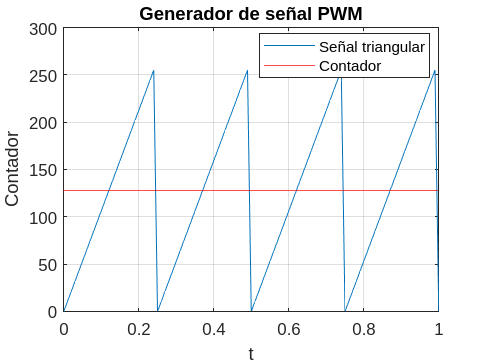

plot(t,y)
hold on
yline(255/2,'r')
grid on
ylabel("Contador")
xlabel("t")
legend("Señal triangular","Contador","Location","best")
title("Generador de señal PWM")

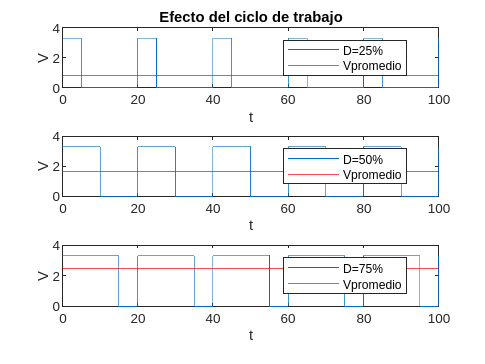

close all
figure(2)
freq=10/200;
offset=0;
amp=3.3/2;
duty=50;
t=0:0.01:100;%100 seconds
sq_wav1=amp+amp*square(2*pi*freq.*t,25);
sq_wav2=amp+amp*square(2*pi*freq.*t,50);
sq_wav3=amp+amp*square(2*pi*freq.*t,75);
subplot(3,1,1)
plot(t,sq_wav1)
yline(0.25*3.3,'r')
title("Efecto del ciclo de trabajo")
ylabel("V")
xlabel("t")
legend("D=25%","Vpromedio","Location","best")
subplot(3,1,2)
plot(t,sq_wav2)
yline(0.5*3.3,'r')
ylabel("V")
xlabel("t")
legend("D=50%","Vpromedio","Location","best")
subplot(3,1,3)
plot(t,sq_wav3)
yline(0.75*3.3,'r')
ylabel("V")
xlabel("t")
legend("D=75%","Vpromedio","Location","best")